# Machine Learning Online Class

## Initialization

## ================ Part 1: Feature Normalization ================

## Clear and Close Figures

clear ; close all; clc

fprintf('Loading data ...\n');

Loading data ...


## Load Data

data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

% Scale features and set them to zero mean
fprintf('Normalizing Features ...\n');

Normalizing Features ...



[X mu sigma] = featureNormalize(X);

% Add intercept term to X
X = [ones(m, 1) X];
disp(X)

    1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237
    1.0000   -0.0764    1.0904
    1.0000   -0.0009   -0.2237
    1.0000   -0.1393   -0.2237
    1.0000    3.1173    2.4045
    1.0000   -0.9220   -0.2237
    1.0000    0.3766    1.0904
    1.0000   -0.8565   -1.5378
    1.0000   -0.9622   -0.2237
    1.0000    0.7655    1.0904
    1.0000    1.2965    1.0904
    1.0000   -0.2940   -0.2237
    1.0000   -0.1418   -1.5378
    1.0000   -0.4992   -0.2237
    1.0000   -0.0487    1.0904
    1.0000    2.3774   -0.2237
    1.0000   -1.1334   -0.2237
    1.0000   -0.6829   -0.2237
    1.0000    0.6610   -0.2237
    1.0000    0.2508   -0.2237
    1.0000    0.8007   -0.2237
    1.0000   -0.2034   -1.5378
    1.0000   -1.2592   -2.8519
    1.00

## ================ Part 2: Gradient Descent ================

% ====================== YOUR CODE HERE ======================
% Instructions: We have provided you with the following starter
%               code that runs gradient descent with a particular
%               learning rate (alpha). 
%
%               Your task is to first make sure that your functions - 
%               computeCost and gradientDescent already work with 
%               this starter code and support multiple variables.
%
%               After that, try running gradient descent with 
%               different values of alpha and see which one gives
%               you the best result.
%
%               Finally, you should complete the code at the end
%               to predict the price of a 1650 sq-ft, 3 br house.
%
% Hint: By using the 'hold on' command, you can plot multiple
%       graphs on the same figure.
%
% Hint: At prediction, make sure you do the same feature normalization.
%

fprintf('Running gradient descent ...\n');

Running gradient descent ...



% Choose some alpha value
alpha = 0.01;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

   6.4301e+10

   6.3037e+10

   6.1799e+10

   6.0587e+10

   5.9400e+10

   5.8238e+10

   5.7100e+10

   5.5986e+10

   5.4894e+10

   5.3825e+10

   5.2779e+10

   5.1754e+10

   5.0750e+10

   4.9767e+10

   4.8804e+10

   4.7861e+10

   4.6938e+10

   4.6033e+10

   4.5148e+10

   4.4280e+10

   4.3431e+10

   4.2598e+10

   4.1783e+10

   4.0985e+10

   4.0203e+10

   3.9437e+10

   3.8687e+10

   3.7953e+10

   3.7233e+10

   3.6528e+10

   3.5838e+10

   3.5162e+10

   3.4499e+10

   3.3850e+10

   3.3215e+10

   3.2592e+10

   3.1983e+10

   3.1385e+10

   3.0800e+10

   3.0227e+10

   2.9665e+10

   2.9115e+10

   2.8576e+10

   2.8048e+10

   2.7531e+10

   2.7025e+10

   2.6528e+10

   2.6042e+10

   2.5566e+10

   2.5099e+10

   2.4642e+10

   2.4194e+10

   2.3755e+10

   2.3325e+10

   2.2904e+10

   2.2492e+10

   2.2087e+10

   2.1691e+10

   2.1303e+10

   2.0923e+10

   2.0551e+10

   2.0186e+10

   1.9828e+10

   1.9478e+10

   1.9134e+10

   1.8798e+10

   1.8468e

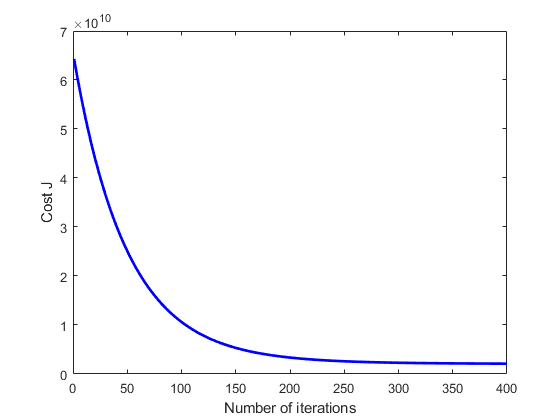


% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');


% Display gradient descent's result
fprintf('Theta computed from gradient descent: \n');

Theta computed from gradient descent: 


fprintf(' %f \n', theta);

 334302.063993 
 100087.116006 
 3673.548451 


fprintf('\n');


% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================
% Recall that the first column of X is all-ones. Thus, it does
% not need to be normalized.
house = [1650, 3] - mu;
house = house ./ sigma

house =    -0.4413   -0.2237


house = [1, house]

house =     1.0000   -0.4413   -0.2237


price = house * theta; % You should change this


% ============================================================

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using gradient descent):\n $%f\n'], price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $289314.620338



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ================ Part 3: Normal Equations ================

fprintf('Solving with normal equations...\n');

Solving with normal equations...



% ====================== YOUR CODE HERE ======================
% Instructions: The following code computes the closed form 
%               solution for linear regression using the normal
%               equations. You should complete the code in 
%               normalEqn.m
%
%               After doing so, you should complete this code 
%               to predict the price of a 1650 sq-ft, 3 br house.
%

## Load Data

data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations: \n');

Theta computed from the normal equations: 


fprintf(' %f \n', theta);

 0.000000 
 0.000000 
 0.000000 


fprintf('\n');



% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================
price = 0; % You should change this


% ============================================================

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using normal equations):\n $%f\n'], price);

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $0.000000
